## Question 1:

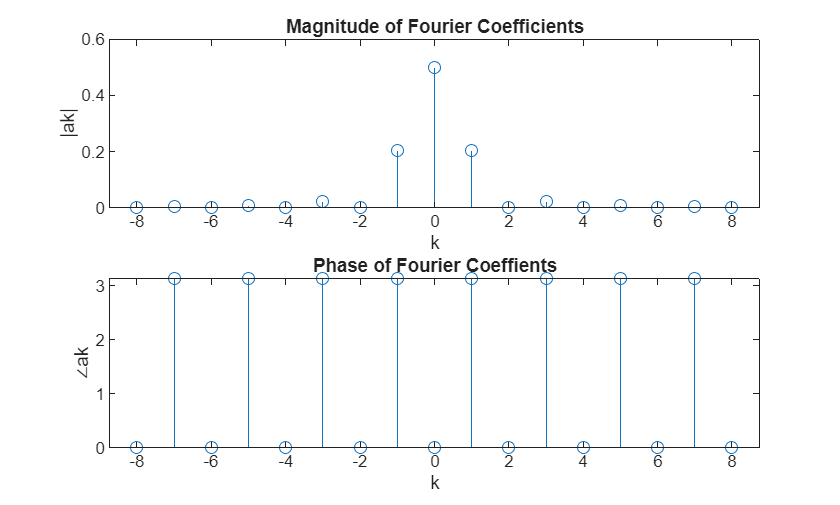

% DC offset
a0 = 0.5;
T = 2;
omega0 = 2*pi/T;

%define integrals
syms Ts w0 t k
f = exp(-j*k*w0*t);
x1 = t + 1;
x2 = -t + 1;

ak_sym = 1/Ts * int(f*x1, t, -1, 0) + 1/Ts * int(f*x2, t, 0, 1);
ak_sub = subs(ak_sym, [Ts, w0], [T, omega0]); %Plug in T and w0

k_vals = -8:8;
ak = zeros(1, length(k_vals));

for idx = 1:length(k_vals)
    k_val = k_vals(idx); 
    %manually set a0
    if k_val == 0 
        ak(idx) = a0;
    else
        ak(idx) = double(subs(ak_sub, k, k_val));
    end
end
ak_mag = abs(ak);

%Now for by hand:
ak = zeros(size(k_vals));

for idx = 1:length(k_vals)
    k = k_vals(idx);
    if k == 0
        ak(idx) = a0;
    else
        ak(idx) = 4/(k*pi)^2 * cos(k*pi); % exactly reproduces integral result
    end
end
ak_phase = angle(ak);



figure;
subplot(2,1,1);
stem(k_vals, ak_mag);
title("Magnitude of Fourier Coefficients")
xlabel('k')
ylabel('|ak|')

subplot(2,1,2);
stem(k_vals, ak_phase);
title("Phase of Fourier Coeffients")
xlabel('k');
ylabel('∠ak');

## Question 2:

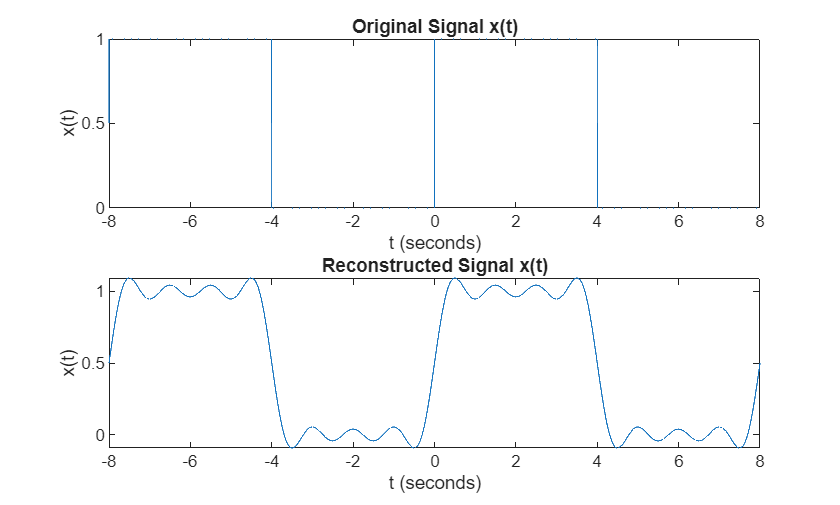

%define x_actual
t = -8:0.001:8;
x_actual = heaviside(t+8) - heaviside(t+4) + heaviside(t) - heaviside(t-4);
x_actual = double(x_actual);

%Note that compared to the worked example, here x_new = x_old(t-2)
%Hence dk = ak*e^(-2jw0k)

%For the old one:
a0 = 0.5;
syms Ts w0 t k

f = exp(-j*k*w0*t);

%integrate over a subset of [-T/2, T/2] where x is non-zero, here [-2, 2]
%and in this interval x = 1:
ak_sym = 1/Ts *int(f, t, -2, 2);
ak_sub = subs(ak_sym, [Ts, w0], [8, pi/4]); %Plug in T and w0
k_vals = -8:8;
ak = zeros(1, length(k_vals));

for idx = 1:length(k_vals)
    k_val = k_vals(idx); 
    %manually set a0
    if k_val == 0 
        ak(idx) = a0;
    else
        ak(idx) = double(subs(ak_sub, k, k_val));
    end
end

%Now get dk from ak:
dk = zeros(1, length(k_vals));
for idx = 1:length(k_vals)
    k_val = k_vals(idx);
    dk(idx) = ak(idx)*exp(-1j*k_val*(2*pi/8)*2);
end

t = -8:0.001:8;

x_reconstruct = zeros(size(t));
Ts = 8;
for idx = 1:length(k_vals)
    x_reconstruct = x_reconstruct + (dk(idx) * exp(1j * k_vals(idx) *2*pi/Ts *t) );
end

x_reconstruct = real(x_reconstruct);
figure;
subplot(2,1,1);
plot(t, x_actual);
title("Original Signal x(t)");
xlabel("t (seconds)");
ylabel("x(t)");
subplot(2,1,2);
plot(t, x_reconstruct);
title("Reconstructed Signal x(t)");
xlabel("t (seconds)");
ylabel("x(t)");